Consider the following coupled cells


$$\dot{x}_j = x_{j+1} + \delta x_j^2x_{j+1}$$



$$\dot{x}_{j+1} = -x_j - (x_j^2 - \lambda)x_{j+1} + \alpha(x_{j-1}-2x_{j+1} + x_{j+3}) + \beta x_jx_{j+1}$$


For $j = 1,3,5$, $x_0 = x_6$, and $x_8 = x_2$ (modular arithmetic). Consider $\lambda$ as a bifurcation parameter and fix the other parameters as follows.

clear

alpha = -0.5;
beta = -1.8;
delta = -0.28;

Because the system is a ring of coupled cells, it is equivariant with respect to $D_3$ symmetry. Indeed,* rotations* involve cyclic permutations, and *reflections *fix exactly one cell while interchanging the other two. Therefore, the fixed point subspaces of the dihedral group are given by $\text{span}(x_j,x_{j+1})$ for $j = 1,3,5$. Furthermore, from *Theorem 8.1*, the following function is a detective.


$$\phi(x) = x\cdot \dot{x}$$


For continuous functions, the time-average is given by

$K_{\phi}^E(x(0)) = \lim_{T\rightarrow \infty}\frac{1}{T}\int_0^Tx(t)\cdot \dot{x}(t) \ dt$.

In the paper, it's unclear how they computed the integral. I will take note of the fact that $(x(t)\cdot x(t))' = 2x(t)\cdot x'(t)$ by the chain rule, so

$\int_0^T x(t)\cdot x'(t) = \frac{1}{2}\int_0^T ((x(t)^2)' = \frac{1}{2}(x(T)^2-x(0)^2)$. I will use a numerical ODE solver to solve for $x(T)$

If we take $\phi_i$ to be the $i^{th}$ component of $K_{\phi}^E$, then the distances we need to compute are 

- 
$$d_1^2 = \phi_3^2 + \phi_4^2 + \phi_5^2 + \phi_6^2$$


- 
$$d_2^2 = \phi_1^2 + \phi_2^2 + \phi_5^2 + \phi_6^2$$


- 
$$d_3^2 = \phi_1^2 + \phi_2^2 + \phi_3^2 + \phi_4^2$$


- 
$$d_4^2 =\phi_1^2 +\phi_2^2 + \phi_3^2 + \phi_4^2 + \phi_5^2+\phi_6^2$$


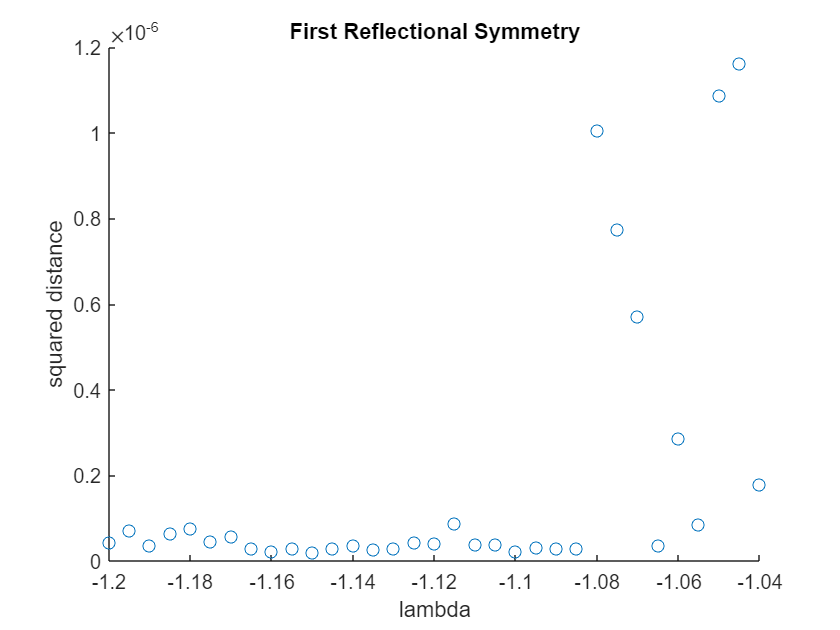

%set seed
rng('default')


%for storing distance to fixed point subspaces
refl1 = [];
refl2 = [];
refl3 = [];
rot = [];

lam_store = [];

%initialization
x0 = [rand; rand; rand; rand; rand; rand];



lambda = -1.2;
l_step  = 5*10^(-3);

%computing distances to fixed point subspace throughout parameter space
%lambda
while lambda <= -1.04
    
    time_avg = erg_avg(x0, alpha, beta, delta, lambda);
    distances = comp_dist(time_avg);

    refl1(end+1) = distances(1);
    refl2(end+1) = distances(2);
    refl3(end+1) = distances(3);
    rot(end+1) = distances(4);
    
    lam_store(end+1) = lambda;

    lambda = lambda + l_step;
end

scatter(lam_store, refl1)
title('First Reflectional Symmetry')
xlabel('lambda')
ylabel('squared distance')

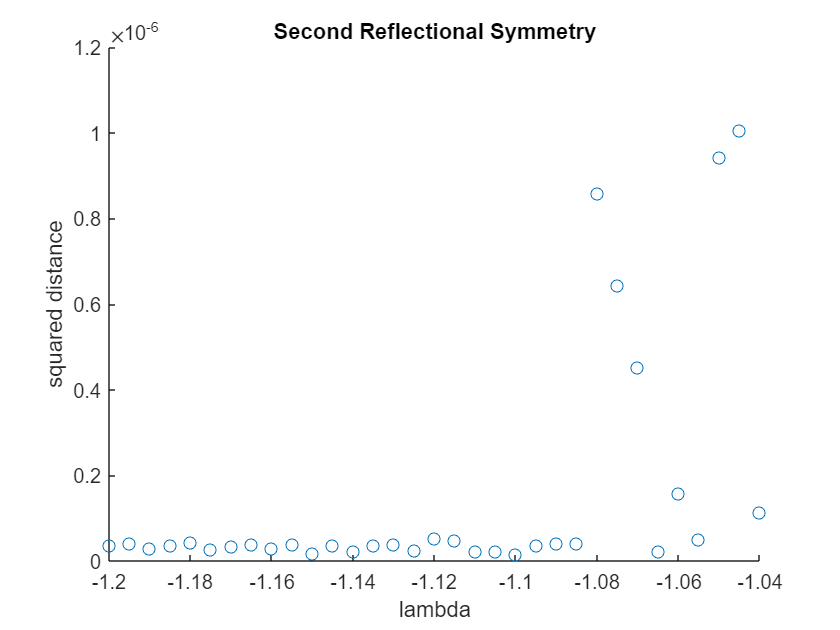


scatter(lam_store, refl2)
title('Second Reflectional Symmetry')
xlabel('lambda')
ylabel('squared distance')

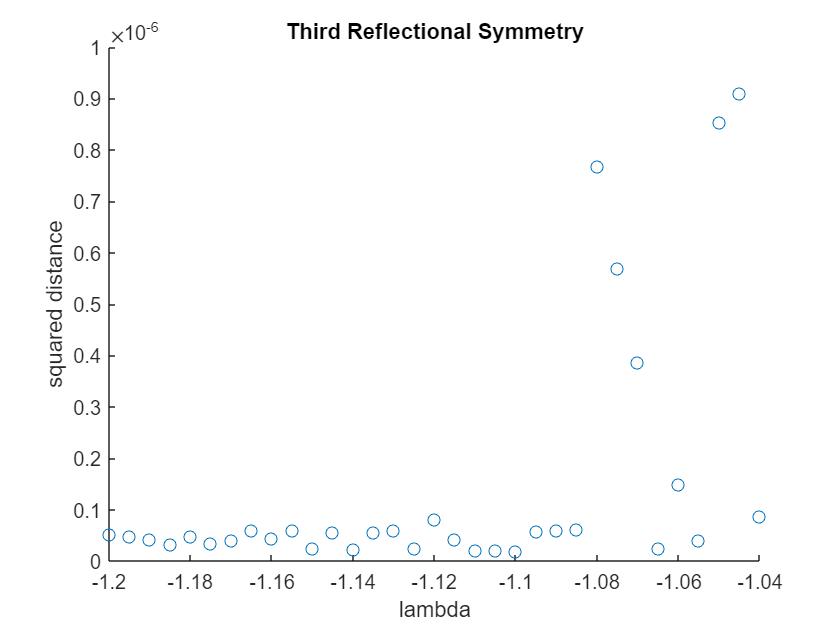


scatter(lam_store, refl3)
title('Third Reflectional Symmetry')
xlabel('lambda')
ylabel('squared distance')

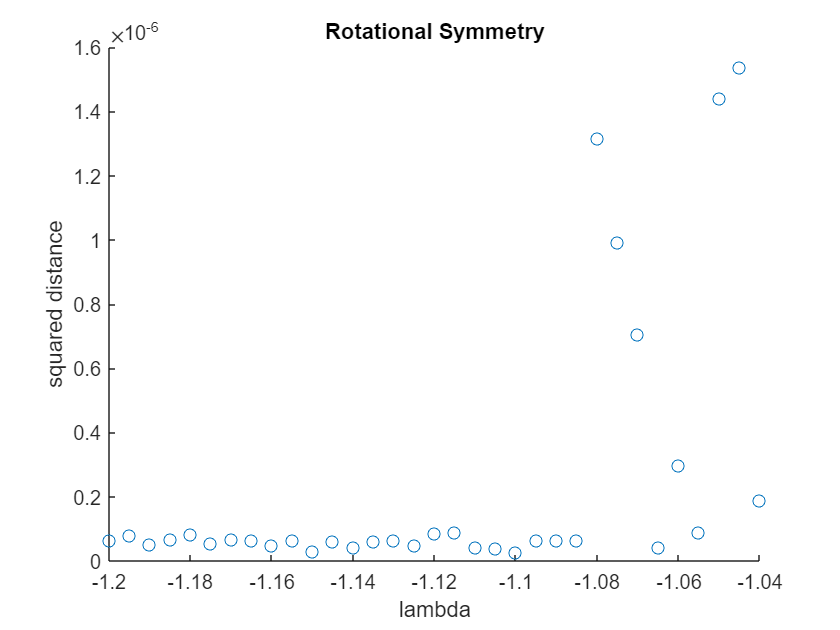


scatter(lam_store, rot)
title('Rotational Symmetry')
xlabel('lambda')
ylabel('squared distance')

function dxdt = odefun(t, x, alpha, beta, delta, lambda)
    dxdt = [x(2)+delta*x(1)^2*x(2);
        -x(1)-(x(1)^2-lambda)*x(2)+alpha*(x(6)-2*x(2)+x(4))+beta*x(1)*x(2);
        x(4)+delta*x(3)^2*x(4);
        -x(3)-(x(3)^2-lambda)*x(4)+alpha*(x(2)-2*x(4)+x(6))+beta*x(3)*x(4);
        x(6)+delta*x(5)^2*x(6);
        -x(5)-(x(5)^2-lambda)*x(6)+alpha*(x(4)-2*x(6)+x(2))+beta*x(5)*x(6)];
end

function time_avg = erg_avg(x0, alpha, beta, delta, lambda)
%This function will compute the time-average of the solution for T =
%n1,n2,n3,... until the series in T converges (approximately), using 
% initial condition x0 (a 6-vector). It will output
%the final time average after convergence.

    %initialization
    T = 1;
    prev_avg = [1;1;1;1;1;1]; %arbitrarily chosen
    time_avg = [2;2;2;2;2;2]; %arbitrarily chosen
    
    while norm(prev_avg - time_avg) > 10^(-3)
        %storing previous time_avg for determining convergence
        prev_avg = time_avg;
    
        %computing the time average up to time T
        [~, int] = ode45(@(t,x) odefun(t,x, alpha, beta, delta, lambda), [0 T], x0);
        %index the value at time T (bottom row)
        time_avg = (1/T)*(1/2)*(int(end,:).^2-x0.^2);
    
        T = T + 10;
    end
end

function sq_dist = comp_dist(time_avg)
%Given the time-average (6-vector), this function will compute the four
%squared distances needed to determine the symmetry of the attractor

    %add square to distances if needed
    dist1 = sum(time_avg(3:6).^2);
    dist2 = sum(time_avg(1:2).^2+time_avg(5:6).^2);
    dist3 = sum(time_avg(1:4).^2);
    dist4 = sum(time_avg.^2);

    sq_dist = [dist1,dist2,dist3,dist4];
end